# Laboratory work: Rendez-vous and tracking

**Task: **A set of mobile robots have to agree on a rendez-vous position and, when they are in proximity to the rendez-vous point, they start a tracking task on a circular trajectory.

clc
clear
close all

## UGVs (Unmanned Ground Veichles) Network

Let's define a network that consists of three nodes, each representing a unicycle with a specific state that defines its position and orientation $q={\left\lbrack x\;y\;\vartheta \right\rbrack }^T$. To set the initial state of all the unicycles, both position and orientation are generated by uniform distributions. In particular:


$$\begin{array}{l}
x\sim U\left(0,10\right)\\
y\sim U\left(0,10\right)\;\\
\vartheta \sim U\left(0,2\pi \right)\;
\end{array}$$


To model the process of comunication between nodes let insert an oriented edge $e_{\textrm{ij}} \left(i\to j\right)$ if node$i$ is accesing to information of node$j$. Let's represent the graph topology by defining the adjacency matrix $A_G$ and not considering self loops:


$$A_{\textrm{ij}} =\;\left\lbrace \begin{array}{ll}
1 & \textrm{if}\;\exists \;\left(i\to j\right)\;\textrm{for}\;i\not= j\\
0 & \textrm{otherwise}
\end{array}\right.$$


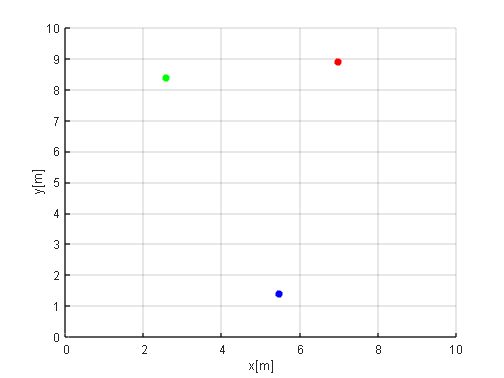

% set space limits
x_limits= [0,10];
y_limits= [0,10];

% set all unicycles initial poses
x1= setPose(x_limits, y_limits);
x2= setPose(x_limits, y_limits);
x3= setPose(x_limits, y_limits);

x1= [6.9908, 8.9090, 6.0274];
x2= [5.4722, 1.3862, 0.9380];
x3= [2.5751, 8.4072, 1.5977];

% state vector
X= [x1;x2;x3];

% set graph adjacency matrix 
A= [1, 0, 0;
    0, 1, 0;
    0, 0, 0];

% plot unicycle comunication network topology 
plot_graph_topology(X, A, x_limits, y_limits);

## NN (Nearest Neighbors) consensus matrix design

Let's apply Nearest Neighbors procedure to provide a solution to the problem of the design of the consensus matrix. The algorithm consists on assigning equal weights to all neighbors taking into account the self-information of each nodes: 

$P_{\textrm{ij}} =\;\left\lbrace \begin{array}{ll}
\frac{1}{1+d_i } & \textrm{if}\;\exists \;\left(i\to j\right)\;\textrm{or}\;\left(i=j\right)\\
0 & \textrm{otherwise}
\end{array}\right.$  with $d_i$ degree of node $i$

% compute network degree matrix 
D= compute_degree_matrix(A);

% design P matrix with NN rule
P= nearest_neighbors_design(A, D);

    0.5000         0         0
         0    0.5000         0
         0         0    0.5000




% check if consensus convergence
consensus_protocol_convergence(P)

ans = 'Matrix P is not Primitive'

% eigenvalues of P
[V,D,W]= eig(P);

## Rendez-vous problem solution

Let's consider the discrete time consensus protocol: $x\left(k+1\right)=P\;x\left(k\right)$.

If the designed matrix $P$ is both stochastic and primitive the consensus protocol convergence to consensus, if $P$ is both doubly stochastic and primitive thenit converges to  average consensus. Let's define usefull parameters for the design of the consensus protocol algorithm and its stopping criteria:

- Maximum number of iterations 

- Desired accuracy of the estimated consensus value 

- Minimum accuracy decrement at each iteration 

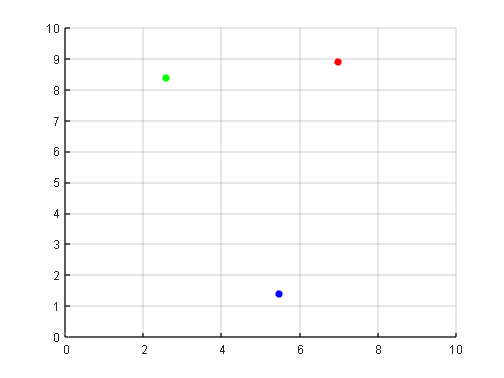

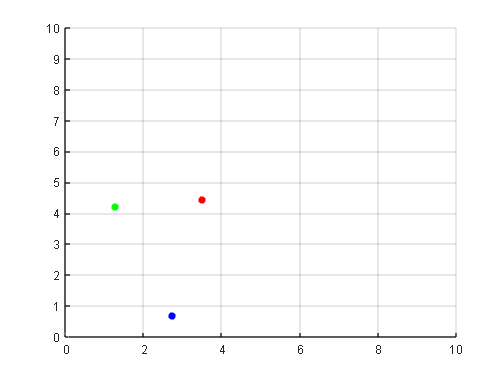

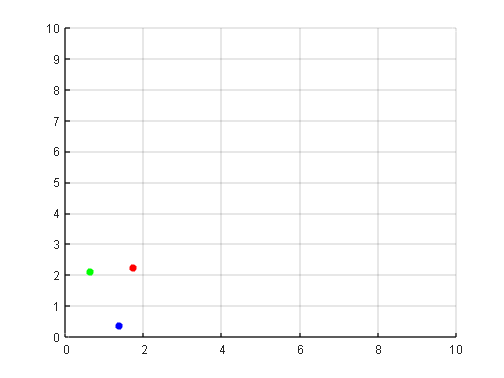

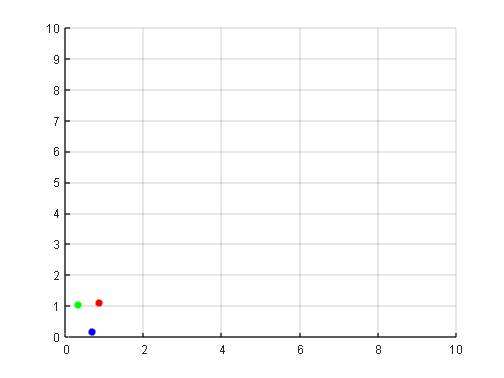

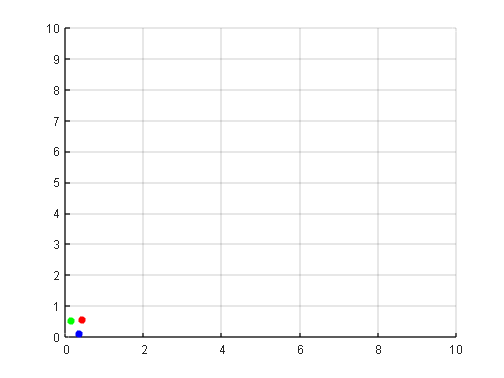

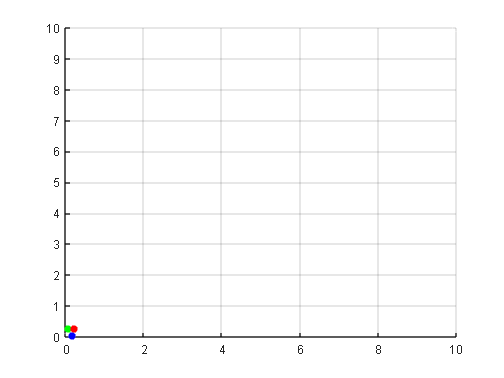

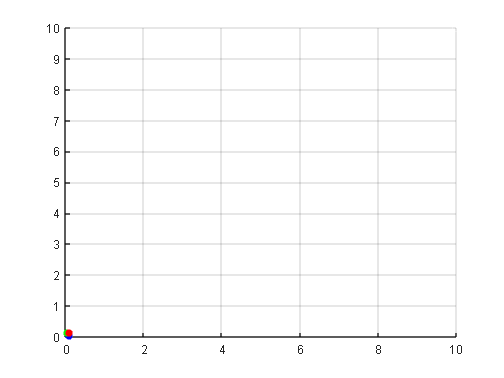

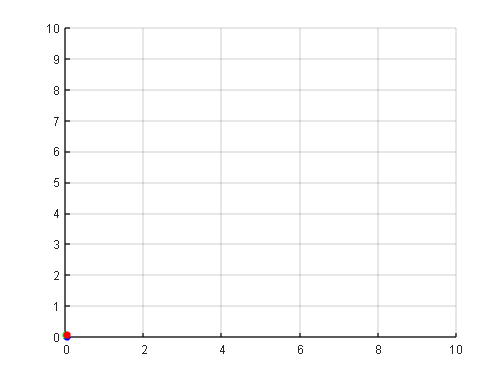

% parameters
max_iters= 15;
accuracy=  0.01;
min_decrement= 0.001;

% compute consensus protocol to solve the rendez-vous destination for each unicycle
[X,k]= consensus_protocol(P, X, max_iters, accuracy, min_decrement, x_limits, y_limits);

## Model Setting and Environment definition

Robotics System Toolbox is used. Let's define a real unicycle model described by the following parameters:

- Wheel radius**: **$0\ldotp 01\;\left\lbrack m\right\rbrack$

- Wheel speed range**: **$\left\lbrack -150,150\right\rbrack \;\left\lbrack \textrm{rad}/s\right\rbrack$ 

### Rendez-Vous Scenario:

Each unicycle initially performs regulation control from its own initial state $q_0$ **toward rendez-vous destination** configuration until it is in its proximity; namely until it reaches a specified distance from destination point. Then, it switches to tracking control to follow a circular path, centered at the rendez-vous point with a desired radius.

- Distance from rendez-vous point: $0\ldotp 5\;\left\lbrack m\right\rbrack$

- Circular Path radius: $1\;\left\lbrack m\right\rbrack$

This scenario is the **accomplish the desired homework task** an it is completely modeled in the simulink file **unicycle.slx.**

### Normalized Scenario:

This scenario is used for **testing** and **tuning** the control scheme's parameters. Regulation and Tracking are **completely** separate; namely ther is no switching behaviour. For regulation, we assume only one unicycle that from initial configuration $q_0 =\left(0,0,0\right)$ must performs point to point control until final configuration $q_f \left(1,1,*\right)$. For tracking we assume again initial position$q_0 =\left(0,0,0\right)$ and to track a circular path, centered at the rendez-vous point with a **fixed **radius $=1$.

This scenario is completely modeled in the simulink file **unicycle_analysis.slx**

% unicycle model parameters
wheel_speed_range= [-150, 150];
wheel_radius= 0.1;

% ctrl parameters
rv_distance= 0.5;
path_radius= 1.1;
radius= path_radius;

% unicycles initial state condition
init_state_1= [x1(1); x1(2); x1(3)];
init_state_2= [x2(1); x2(2); x2(3)];
init_state_3= [x3(1); x3(2); x3(3)];

% unicycles destinations
x1_dest= [X(1,1), X(1,2)];
x2_dest= [X(2,1), X(2,2)];
x3_dest= [X(3,1), X(3,2)];

% define which scenario to plot the results
% scenario 1: 'Scenario: Normalized'
% scenario 2: 'Scenario: Rendez-vous'
scenario=  2;

## Control Parameters

Here let's define the parameters that will be used in both of the simulink files.

kv= 0.8;                            % regulation linear velocity gain 
kw= 5.5;                            % regulation angular velocity gain

damping_coefficient= 0.7;           % linear state feedback: damping coefficient in [0,1]
natural_frequency=   3.5;           % linear state feedback: natural frequency >0

damping_coefficient_nl= 0.8;        % non linear state feedback: damping coefficient in [0,1] 
natural_frequency_nl= 4.0;          % non linear state feedback: natural frequency >0

b_reference_point= 0.3;             % point on sagittal axis
k1= 2.6;                            % feedback linearization gain 1
k2= 2.6;                            % feedback linearziation gain 2

kp1= 2.0;                           % feedback linearization with derivatives gain 1
kp2= 2.0;                           % feedback linearization with derivatives gain 2
kp3= 2.0;                           % feedback linearization with derivatives gain 3
kp4= 2.0;                           % feedback linearization with derivatives gain 4

### Run simulations

In this section let run the simulink simulation and store the switching time instant that is usefull for plotting.

% run both the simulink simulation:
% rendez-vous control simulation
% normalized control simulation
out=  sim("unicycle.slx"); 
out1= sim("unicycle_analysis.slx");

% find the indexe associated to controller switching time instant  
switch_1= switch_instant(out.SwitchUnicycle1.signals.values);
switch_2= switch_instant(out.SwitchUnicycle2.signals.values);
switch_3= switch_instant(out.SwitchUnicycle3.signals.values);

% compute the controller switching time instant
switch_time1= out.SwitchUnicycle1.time(switch_1);
switch_time2= out.SwitchUnicycle2.time(switch_2);
switch_time3= out.SwitchUnicycle3.time(switch_3);

## Unicycle Control Simulation

In this section we aim to test the control scheme designed for the unicycle robots in the specific scenario described in the assignment. Given unicycles initial positions and rendez-vous destination points, let's plot the trajectories to visually confirm the accuracy and stability of the control scheme and evaluate the performance of the control algorithms. So, let's run simulink file **unicycle.slx, **log all the necessary data and plot the trajectories of each unicycles.

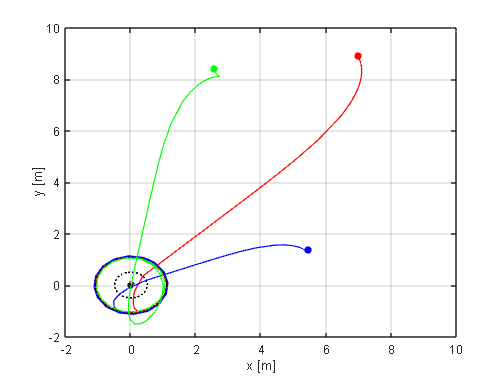

% simulink data-logging - unicycles states 
state_1= out.StateUnicycle1.signals;
state_2= out.StateUnicycle2.signals;
state_3= out.StateUnicycle3.signals;

% plot all unicycles trajectories both in regualation and tracking control phases by exploiting simulink data logging of unicycles generalized states 
plot_regulation_tracking(x1,x2,x3, state_1.values,state_2.values,state_3.values, x1_dest,x2_dest,x3_dest, x_limits,y_limits, path_radius,rv_distance)

### Regulation: Cartesian Control

Since in our case the rendez-vous destination point is specified only in terms of position, our task is to drive the unicycle to a desired configuration in terms of just position $p$ regardless the orientation $\vartheta$. The adopted control law, that acts on the velocity pair $\left(v,\omega \right)$, is the following:


$$\begin{array}{l}
v\;=\;k_v \;\left(-\textrm{xcos}\vartheta -\textrm{ysin}\vartheta \right)\\
\omega =k_w \;\left(\textrm{atan2}\left(y,x\right)+\pi -\vartheta \right)
\end{array}$$
 

Note that the final orientation of the robot varies with the approach direction, and that the unicycle reaches the destination in forward motion, after inverting its motion at most once. It is  possible to prove that such a behaviour is general with this controller.

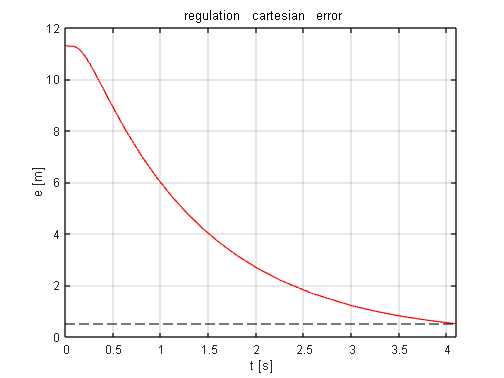

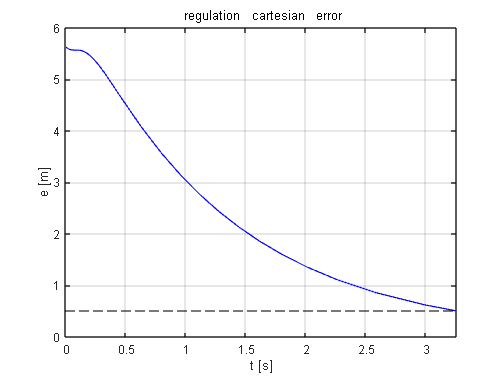

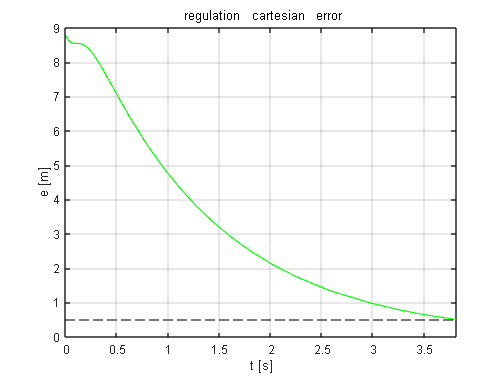

% plot the unicycle state trajectory and the associated circular path reference trajectory dependently on the choice of the user of plotting the normalized scenario or homework task simulations
plot_results_regulation(2, out1.AnalysisStateUnicycle1, out1.AnalysisInputsUnicycle1, out.DistanceFromRVpoint1, 1, switch_time1, out.DistanceFromRVpoint2, 2, switch_time2, out.DistanceFromRVpoint3, 3, switch_time3, rv_distance)

### **Tracking Control: Linear controller of the state error dynamics**

The unicycle error dynamics in their non-linear form are expressed as:


$$\left\lbrace \begin{array}{l}
{\dot{e} }_1 =v_d {\textrm{cose}}_3 -v+e_2 \omega \\
{\dot{e} }_2 =v_d \sin e_3 -e_1 \omega \\
{\dot{e} }_3 =\omega_d -\omega 
\end{array}\right.$$


One can perform linearization around the reference trajectory where the error is zero $e\approx 0$, and hence the linearized error dynamics can be represented as:


$$e^{\prime } =\left\lbrack \begin{array}{ccc}
0 & \omega^{\textrm{des}}  & 0\\
-\omega^{\textrm{des}}  & 0 & v^{\textrm{des}} \\
0 & 0 & 1
\end{array}\right\rbrack \;e+\left\lbrack \begin{array}{ccc}
\;\;\;1 & 0 & \\
\;\;\;0 & 0 & \\
\;\;\;0 & 1 & 
\end{array}\right\rbrack \;\left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack$$


Then, a **Linear state feedback control** law, of the from $u=-\textrm{Ke}$, is proposed to ensure the asymptotic convergence of the error to zero. In our case we utilized the possible control law:


$$\left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
-k_1  & 0 & 0\\
0 & -k_2  & -k_3 
\end{array}\right\rbrack \;e$$
 

with gains $k_1 ,k_2 ,k_3 \;$ are chosen to place the eigenvalues of the closed-loop system in locations that ensure stability and desired performance characteristics. Let's define the damping factor $\xi$, and natural frequency $a$. A possible choice of gains is: $k_1 =k_3 =2\xi a$ and $k_2 =\frac{a^2 -\omega_d^2 }{v_d }$. 

Instead, **Non-linear state feedback** aims to designing a control law that addresses the inherent non-linearities of the system to achieve tracking of a desired trajectory.  These dynamics are non-linear, coupled, and time-varying, making the control design more challenging compared to linear systems. With an invertible input transformation:


$$\left\lbrace \begin{array}{l}
u_1 =v_d {\textrm{cose}}_3 -v\\
u_2 =\omega_d -\omega 
\end{array}\right.$$


 A possible control law is:

              
$$u=-K\left(e\right)e$$
     
$$\Rightarrow$$
       
$$\left\lbrace \begin{array}{ll}
u_1 =-k_1 e_1  & \\
u_2 =-k_2 e_2 -k_3 e_3  & 
\end{array}\right.$$

$$\Rightarrow$$
   
$$\left\lbrace \begin{array}{ll}
k_1 =k_3 =2\xi a & \\
k_2 =\frac{a^2 -\omega_d^2 }{v_d } & 
\end{array}\right.$$
    
$$\textrm{with}\;\xi \in \left(0,1\right)$$
 
$$\textrm{and}$$
 
$$a>0$$
 

where $K$ is a gain matrix that may depend on the state error $e$, and the gains are chosen to stabilize the non-linear error dynamics, ensuring that the system can follow the desired trajectory accurately.

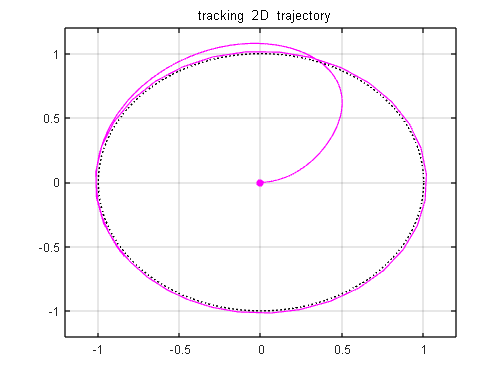

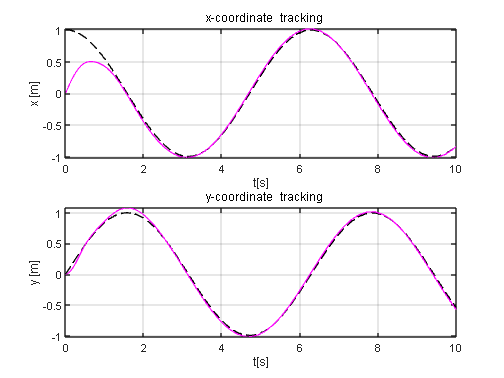

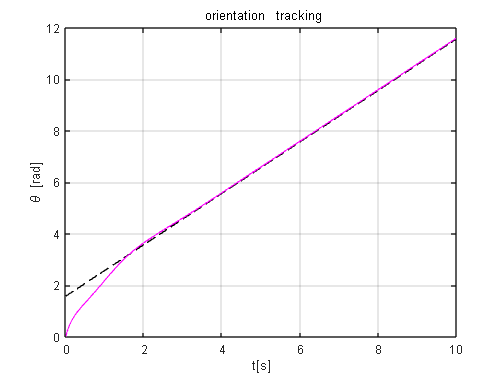

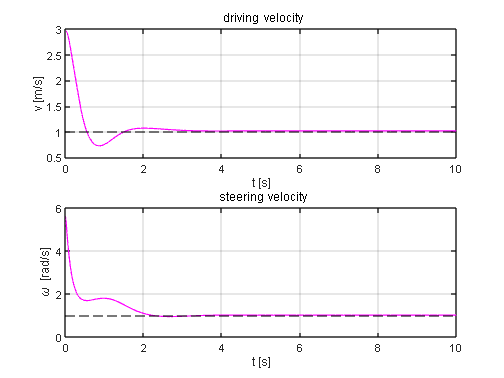

mse = 0.4065

mie = 4.5620

% plot the unicycle state trajectory and the associated circular path reference trajectory dependently on the choice of the user of plotting the normalized scenario or homework task simulations
plot_results(1, out1.AnalysisReferenceUnicycle3, out1.AnalysisStateUnicycle3, out1.AnalysisInputsUnicycle3, out.ReferenceUnicycle1, out.StateUnicycle1, out.VelocityInput1, switch_1, switch_time1, 1, true)

### **Tracking Control: Feedback linearization based on a reference point on the sagittal axis**

Feedback linearization is based on the idea of finding an **invertible** **map** between input and output which can be used to linearize the system dynamic. Let define a **reference point** $b$ along the sagittal axis to slighty change the coordinate frame:

 
$$\left\lbrace \begin{array}{ll}
x_b =x+b\;\cos \left(\vartheta \right) & \\
y_b =y+b\;\sin \left(\vartheta \right) & 
\end{array}\right.$$

$$\Rightarrow$$
    
$$\left\lbrack \begin{array}{c}
{x^{\prime } }_b \\
{y^{\prime } }_b 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\cos \left(\vartheta \right) & -b\;\sin \left(\vartheta \right)\\
\sin \left(\vartheta \right) & b\;\cos \left(\vartheta \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v\\
w
\end{array}\right\rbrack \;$$


Hence, let's define the new input $\left(u_1 ,u_2 \right)\;$such that:


$$\left\lbrack \begin{array}{c}
v\\
\omega 
\end{array}\right\rbrack ={T\left(\vartheta \right)}^{-1} \;\left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack =\;\left\lbrack \begin{array}{cc}
\cos \left(\vartheta \right) & \sin \left(\vartheta \right)\\
-\frac{\sin \left(\vartheta \right)}{b} & \frac{\cos \left(\vartheta \right)}{b}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack$$
 

With this change of input, the system shows decoupled dynamics in the first two components referring to the Cartesian position: ${x_b }^{\prime } =u_1$, ${y_b }^{\prime } =u_2$ and the orientation evolves dependently on it. The proposed **PD **controller is of the form:


$$\left\lbrace \begin{array}{ll}
u_1 =k_1 \left(x_b^{\textrm{des}} -x_b \right)+{x^{\prime } }_b^{\textrm{des}}  & \\
u_2 =k_2 \left(y_b^{\textrm{des}} -y_b \right)+y_b^{\textrm{des}}  & 
\end{array}\right.$$
 
$$\textrm{with}\;k_1 ,k_2 >0$$


**Note: **The choice of parameter $b$ is fundamental in the perspective of reaching good control performances. In particular, smaller $b,\;$better the performances.

The choice of parameter $b$is fundamental. By reducing $b$as closa a $0$ one can achieve more accurate tracking but the steering velocity  is much higher in correspondence of the initial instants (when the configuration of the unicycle is far from the reference point) and this can be a problem. This situation is consistent with the fact that matrix $T$tends to become singular when $b$approaches to $0$.

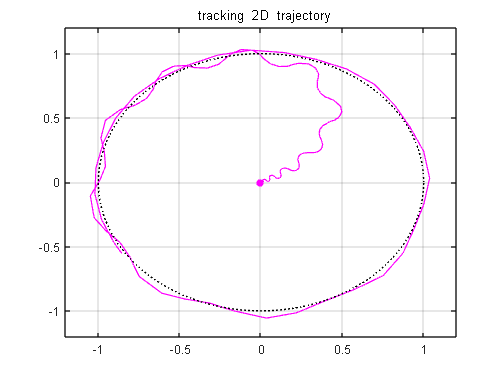

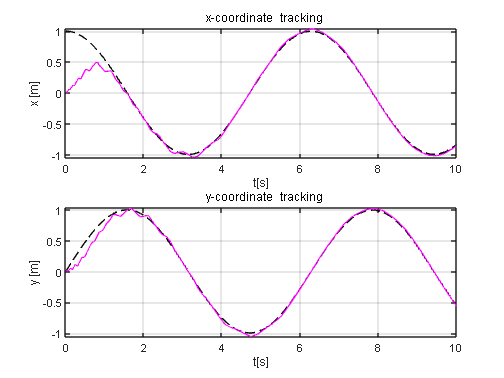

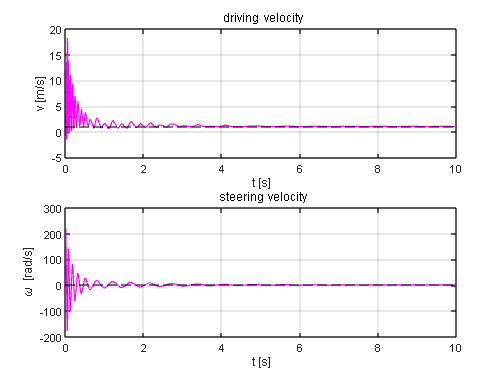

mse = 0.4764

mie = 47.6991

% plot the unicycle state trajectory and the associated circular path reference trajectory
plot_results(1, out1.AnalysisReferenceUnicycle4, out1.AnalysisStateUnicycle4, out1.AnalysisInputsUnicycle4, out.ReferenceUnicycle2, out.StateUnicycle2, out.VelocityInput2, switch_2, switch_time2, 2, false)

### Tracking Control: Feedback linearization based on second order derivatives

Let's apply again Feedback Linearization. Assume $v\not= 0$, then the following map is non singular. Hence, let's define the new input $\left(u_1 ,u_2 \right)\;$such that:


$$\left\lbrack \begin{array}{c}
\ddot{x} \\
\ddot{y} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\cos \left(\vartheta \right) & -v\;\sin \left(\vartheta \right)\\
\sin \left(\vartheta \right) & v\;\cos \left(\vartheta \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{v} \\
w
\end{array}\right\rbrack \;$$
 
$$\;\;\;\Rightarrow \;\;\;\;$$
 
$$\left\lbrack \begin{array}{c}
\dot{v} \\
\omega 
\end{array}\right\rbrack =\;\left\lbrack \begin{array}{cc}
\cos \left(\vartheta \right) & \sin \left(\vartheta \right)\\
-\frac{\sin \left(\vartheta \right)}{v} & \frac{\cos \left(\vartheta \right)}{v}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack$$


Then the system becomes:


$$\left\lbrace \begin{array}{ll}
z_1 =x & \\
z_2 =y & \\
z_3 =\dot{x} =v\;\cos \left(\vartheta \right) & \\
z_4 =\dot{y\;} =\textrm{vsin}\left(\vartheta \right) & 
\end{array}\right.$$

$$\;\Rightarrow \;$$

$$\left\lbrace \begin{array}{ll}
\dot{z_1 } =z_3  & \\
\dot{z_2 } =z_4  & \\
\dot{z_3 } =\ddot{x} =u_1  & \\
\dot{z_4 } =\ddot{y} =u_2  & 
\end{array}\right.$$

$$\;\Rightarrow \;$$

$$\begin{array}{l}
\ddot{z_1 } =u_1 \\
\ddot{z_2 } =u_2 
\end{array}$$


The possible linear controller can be designed in PD form as:


$$\begin{array}{l}
u_1 =k_{p_1 } \left(x_d -x\right)+k_{d_1 } \left(\dot{x_d } -\dot{x} \right)+\ddot{x_d } \\
u_2 =k_{p_2 } \left(y_d -y\right)+k_{d_2 } \left(\dot{y_d } -\dot{y} \right)+\ddot{y_d } 
\end{array}$$


**Note: **In our case the unicycle has initial velocity equal to zero and the transformation matrix becomes singular. Then, just in the initial instant, one can change the transformation $\omega =-\frac{\sin \left(\vartheta \right)}{v}u_1 +\frac{\cos \left(\vartheta \right)}{v}u_2 \;$ to $\omega =-\vartheta u_1 +u_2$ 

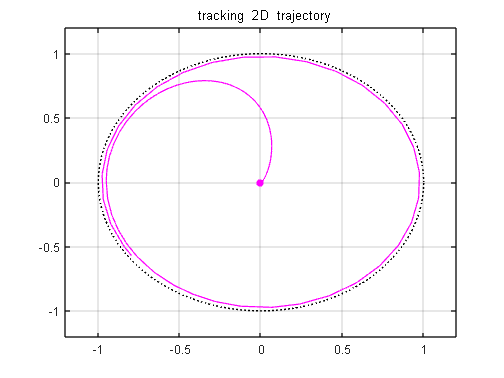

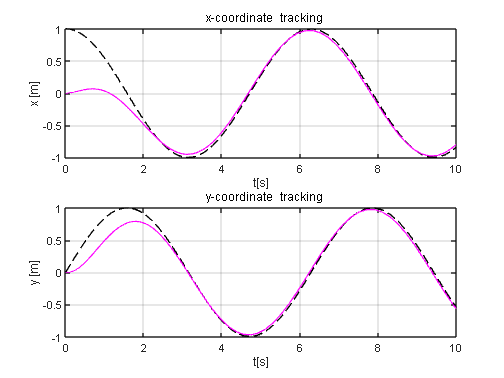

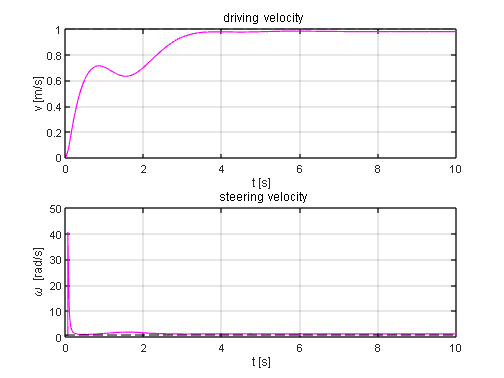

mse = 0.5932

mie = 3.7367

% plot the unicycle state trajectory and the associated circular path reference trajectory
plot_results(1, out1.AnalysisReferenceUnicycle5, out1.AnalysisStateUnicycle5, out1.AnalysisInputsUnicycle5, out.ReferenceUnicycle3, out.StateUnicycle3, out.VelocityInput3 ,switch_3,switch_time3, 3, false)

% function to set a single unicycle random initial pose
% x_limits_: x upper/lower endpoints of U distribution 
% x_limits_: y upper/lower endpoints of U distribution 
function x_= setPose(x_limits_, y_limits_)
    x= unifrnd(x_limits_(1), x_limits_(2));
    y= unifrnd(y_limits_(1), y_limits_(2));
    t= unifrnd(0, 2*pi);
    x_= [x, y, t];
end


% function to perform full consensus protocol
% P_: Perron Matrix
% x_: state vector
% k_: max number of iterations
% e_: consensus accuracy threshold
% x_limits_: x upper/lower endpoints of U distribution
% x_limits_: y upper/lower endpoints of U distribution
function [x,k]= consensus_protocol(P_,x_,k_,e_, i_, x_limits_, y_limits_)
    x_(:,3)=0;
    it= 0;
    avg= distances_average(x_);
    increment= Inf;
    figure
    plot_rendez_vous(P_, x_,  x_limits_, y_limits_);
    while (it<k_) && (avg>e_) && (increment>i_)
        x_= P_*x_;
        increment= avg-distances_average(x_);
        avg= distances_average(x_);
        figure
        plot_rendez_vous(P_, x_, x_limits_, y_limits_);
        it= it+1;
    end
    x=x_;
    k= it;
end


% function to compute average between unicycle distances
% x_: pose state vector
function avg= distances_average(x_)
    n1= norm(x_(1,:)-x_(2,:), 2);
    n2= norm(x_(2,:)-x_(3,:), 2);
    n3= norm(x_(3,:)-x_(1,:), 2);
    avg= (n1+n2+n3)/3;
end


% function to compute the degree matrix of digraph given:
% A_: adjacency matrix
function D= compute_degree_matrix(A_)
    n= size(A_,1);
    deg_vector= zeros(n,1);
    for i= 1:n
        for j= 1:n
            deg_vector(i,1)= deg_vector(i,1)+ A_(i,j);
        end
    end
    D= diag(deg_vector);
end


% function to design P matrix with NN rule
% A_: adjacency matrix
% D_: degree matrix
function P= nearest_neighbors_design(A_, D_)
    n= size(A_, 1);
    for i= 1:n
        for j= 1:n
            if A_(i,j)==1 || i==j
                A_(i,j)= 1/(1+D_(i,i));
            end
        end
    end
    P=A_;
    disp(P)
end


% function to check sthocasticity of a given square matrix
% P_: square matrix
function isS= isSthocastic(P_)
    isS= true;
    n= size(P_, 1);
    for i=1:n
        sum_by_rows=0;
        for j=1:n
            sum_by_rows= sum_by_rows + P_(i,j);
        end
        if sum_by_rows~=1
            isS= false;
            break;
        end
    end
end


% function to check double sthocasticity of a given square matrix
% P_: square matrix
function isDS= isDoubleStochastic(P_)
    isDS= true;
    n= size(P_,1);
    for j=1:n
        sum_by_cols= 0;
        for i=1:n
            sum_by_cols= sum_by_cols + P_(i,j);
        end
        if sum_by_cols~=1
            isDS= false;
            break
        end
    end
    if isDS && isSthocastic(P_)
        isDS= true;
    else
        isDS= false;
    end
end


% function to check if a given square matrix is primitive
% P_: square matrix
function isPrim= isPrimitive(P_)
    isPrim= true;
    n= size(P_, 1);
    k= (n-1)^2 + 1;
    for i=1:k
        P_= P_*P_;
    end
    
    for i=1:n
        for j=1:n
            if P_(i,j)<=0
                isPrim= false;
                break
            end
        end
        if isPrim== false
           break
        end
    end
end


% function to check sufficient condition to consensus 
% P_: square matrix
function isCons= isConsensus(P_)
    isCons= false;
    if isPrimitive(P_) && isSthocastic(P_)
        isCons= true;
    end
end


% function to check sufficient condition to average consensus
% P_: square matrix
function isAvgCons= isAvgConsensus(P_)
    isAvgCons= false;
    if isPrimitive(P_) && isDoubleStochastic(P_)
        isAvgCons= true;
    end
end


% function to define the convergence of consensu protocol
% by applying the Perron-Frobenius theorem corollary
% P_: matrix P_
function convergenceString= consensus_protocol_convergence(P_)
    if  isAvgConsensus(P_)
        convergenceString= 'Consensus Protocol converge to: Average Consensus';
    elseif isConsensus(P_)
        convergenceString= 'Consensus Protocol converge to: Consensus';
    else
        if isPrimitive(P_) == false
            convergenceString= 'Matrix P is not Primitive';
        elseif isSthocastic(P_) == false
            convergenceString= 'Matrix P is not Sthocastic';
        end        
    end    
end


% function to plot the topology of comunication 3X3 graph
% x_: state vector
% A_: adjacency matrix
% x_limits_: x upper/lower endpoints
% y_limits_: y upper/lower endpoints
function plot_graph_topology(x_, A_, x_limits_, y_limits_)
    drawArrow = @(x,y,varargin) quiver( x(1),y(1),x(2)-x(1),y(2)-y(1),0, varargin{:});
    scatter(x_limits_(1), y_limits_(1), 'white');
    hold on
    grid on
    scatter(x_limits_(2), y_limits_(2), 'white');    
    if A_(1,2)==1 drawArrow([x_(1,1), x_(2,1)],[x_(1,2), x_(2,2)],'linewidth',0.5,'color','cyan');end 
    if A_(1,3)==1 drawArrow([x_(1,1), x_(3,1)],[x_(1,2), x_(3,2)],'linewidth',0.5,'color','cyan');end
    if A_(2,1)==1 drawArrow([x_(2,1), x_(1,1)],[x_(2,2), x_(1,2)],'linewidth',0.5,'color','cyan');end
    if A_(2,3)==1 drawArrow([x_(2,1), x_(3,1)],[x_(2,2), x_(3,2)],'linewidth',0.5,'color','cyan');end
    if A_(3,1)==1 drawArrow([x_(3,1), x_(1,1)],[x_(3,2), x_(1,2)],'linewidth',0.5,'color','cyan');end
    if A_(3,2)==1 drawArrow([x_(3,1), x_(2,1)],[x_(3,2), x_(2,2)],'linewidth',0.5,'color','cyan');end
    scatter(x_(2,1), x_(2,2), "filled", 'b');
    scatter(x_(3,1), x_(3,2), "filled", 'g');
    scatter(x_(1,1), x_(1,2), "filled", 'r'); 
    xlabel('x[m]');
    ylabel('y[m]');
    hold off %#ok<*SEPEX>
end


% function to plot the rendez vous problem
% x_: state vector
% x_limits_: x upper/lower endpoints
% y_limits_: y upper/lower endpoints
function plot_rendez_vous(P_, x_, x_limits_, y_limits_)
    drawArrow = @(x,y,varargin) quiver( x(1),y(1),x(2)-x(1),y(2)-y(1),0, varargin{:});
    scatter(x_limits_(1), y_limits_(1), 'white');
    grid on
    hold on
    scatter(x_limits_(2), y_limits_(2), 'white');
    if P_(1,2)~=0 drawArrow([x_(1,1), x_(2,1)],[x_(1,2), x_(2,2)],'linewidth',0.5,'color','cyan');end
    if P_(1,3)~=0 drawArrow([x_(1,1), x_(3,1)],[x_(1,2), x_(3,2)],'linewidth',0.5,'color','cyan');end
    if P_(2,1)~=0 drawArrow([x_(2,1), x_(1,1)],[x_(2,2), x_(1,2)],'linewidth',0.5,'color','cyan');end
    if P_(2,3)~=0 drawArrow([x_(2,1), x_(3,1)],[x_(2,2), x_(3,2)],'linewidth',0.5,'color','cyan');end
    if P_(3,1)~=0 drawArrow([x_(3,1), x_(1,1)],[x_(3,2), x_(1,2)],'linewidth',0.5,'color','cyan');end
    if P_(3,2)~=0 drawArrow([x_(3,1), x_(2,1)],[x_(3,2), x_(2,2)],'linewidth',0.5,'color','cyan');end
    scatter(x_(2,1), x_(2,2), "filled", 'b');
    scatter(x_(3,1), x_(3,2), "filled", 'g');
    scatter(x_(1,1), x_(1,2), "filled",'r');
    hold off
end


% function to plot the reference circular trajectory
% x: x-cordinate of the center
% y: y-cordinate of the center
% r: radius of the circle
function h = circle(x ,y ,r)
    th = 0:pi/50:2*pi;
    xunit = r * cos(th) + x;
    yunit = r * sin(th) + y;
    h = plot(xunit, yunit, 'k', LineStyle=':');
end


% function to identify the elementof the switching control scheme
% S: vector containing:
% 0 if regulation scheme is active
% 1 if tracking schem is active
function instant= switch_instant(S)
    instant=1;
    for t=1: length(S)
        if S(t)==1
            instant=t;
            break
        end
    end
end


% function to compute the MSE(Mean Squared Error) 
% reference_trajectory: trajectory to track
% unicycle_trajectory: unicycle tracking trajectory
% switch_: switchin instant time from regulation to tracking 
function mse= MSE(reference_trajectory, unicycle_trajectory, switch_)
    n=size(reference_trajectory.time,1);
    init= switch_+1;
    xd= reference_trajectory.signals.values(init:n-1,1);
    yd= reference_trajectory.signals.values(init:n-1,2);
    x= unicycle_trajectory.signals.values(init:n-1,1);
    y= unicycle_trajectory.signals.values(init:n-1,2);
    x_squared_diff= (xd-x).^2;
    y_squared_diff= (yd-y).^2;
    squared_diff= x_squared_diff+y_squared_diff;
    mse= mean(squared_diff(:));
end

% function to compute the MIE (Mean Input Effort)
% input: driving velocity input and steering velocity input
% switch_: switchin instant time from regulation to tracking
function mie= MIE(input, switch_)
    n= size(input.time,1);
    init_inst= switch_+1;
    v= input.signals.values(init_inst:n-1, 1);
    w= input.signals.values(init_inst:n-1, 2);
    absolute_sum_inputs= abs(v)+abs(w);
    mie= mean(absolute_sum_inputs);
end


% function to plot the regulation state in the regularized case
% state_: state trajectory of unicycle 
function plot_regulation(state_)
    figure
    subplot(2,1,1)
    plot(state_.time, state_.signals.values(:,1), "Color","magenta", LineWidth=1);
    hold on
    grid on
    yline(1, 'k', LineStyle='--');
    ylim([-0.1, 1.1])
    xlim([0, 10]);
    xlabel('t [s]');
    ylabel('x [m]');
    title('\rm regulation: x-coordinate trajectory')
    subplot(2,1,2)
    plot(state_.time, state_.signals.values(:,2),"Color","magenta", LineWidth=1);
    hold on
    grid on
    yline(1, 'k', LineStyle='--');
    xlim([0, 10]);
    ylim([-0.1, 1.1])
    xlabel('t [s]');
    ylabel('y [m]');
    title('\rm regulation y-coordinate trajectory')
    hold off
end

%funtion to plot the trajectory in 2d space
% state_: state trajectory of unicycle 
function plot_regulation_trajectory(state_)
    figure
     plot(state_.signals.values(:,1), state_.signals.values(:,2), "Color","magenta", LineWidth=1);
     hold on
     grid on
     scatter(0,0, "filled", 'magenta');
     scatter(1,1, "filled", 'magenta');
     xlim([-0.1, 1.1]);
     ylim([-0.1, 1.1]);
     xlabel('x [m]');
     ylabel('y [m]');
     title('\rm regulation 2D trajectory')
end

% function to plot the trajectory of the velocity inputs
% inputs_: driving velocity and steering velocity
function plot_regualtion_velocities_inputs(inputs_)
    figure
    subplot(2,1,1)
    plot(inputs_.time, inputs_.signals.values(:,1), "Color","magenta", LineWidth=1);
    hold on
    grid on
    yline(1, 'k', LineStyle='--');
    xlabel('t [s]');
    ylabel('v [m/s]');
    title('\rm driving velocity')
    subplot(2,1,2)
    plot(inputs_.time, inputs_.signals.values(:,2),"Color","magenta", LineWidth=1);
    hold on
    grid on
    yline(1, 'k', LineStyle='--');
    xlabel('t [s]');
    ylabel('\omega [rad/s]');
    title('\rm steering velocity')
    hold off
end

%funtion to plot the trajectory in 2d space
% state_: state trajectory of unicycle 
function plot_regulation_results(state_, inputs_)
    plot_regulation(state_);
    plot_regulation_trajectory(state_);
    plot_regualtion_velocities_inputs(inputs_);
    % Extract time and response data from the simulation output
    time = state_.time(:,1);
    response1 = state_.signals.values(:,1);
    response2 = state_.signals.values(:,2);
    response=[response1,response2];
    % Analyze the step response
    info = stepinfo(response, time);
    % Display rise time and settling time
    rise_time = info.RiseTime;
    settling_time = info.SettlingTime;
    disp(['Rise Time: ', num2str(rise_time)]);
    disp(['Settling Time: ', num2str(settling_time)]);
end


function plot_orientation_tracking_trajectory_normalized(reference_, state_)
    figure
    plot(reference_.time, reference_.signals.values(:,3), 'k', LineStyle='--');
    hold on
    grid on
    plot(state_.time, state_.signals.values(:,3), "Color","magenta", LineWidth=1);
    xlabel('t[s]');
    xlim([0, 10])
    ylabel('\theta [rad]');
    title('\rm orientation tracking');
end


function plot_2D_tracking_trajectory_normalized(state_)
    figure 
    plot(state_.signals.values(:,1), state_.signals.values(:,2), "Color","magenta", LineWidth=1);
    hold on
    grid on
    circle(0, 0, 1);
    scatter(0,0, "filled", 'magenta');
    title('\rm tracking 2D trajectory');
    xlim([-1.2, 1.2]);
    ylim([-1.2, 1.2]);
end

% function to plot the unicycle tracking of all the references trajectory
% reference_: trajectory reference object signals
% state_:  unicycle state object signals
% isOrientationTracked: true if it is used a scheme based on orientation tracking
function plot_tracking_trajectory_normalized_case(reference_, state_, inputs_, isOrientationTracked)
    plot_2D_tracking_trajectory_normalized(state_);
    figure
    subplot(2,1,1);
    plot(reference_.time, reference_.signals.values(:,1), 'k', LineStyle='--');
    hold on
    grid on
    plot(state_.time, state_.signals.values(:,1), "Color","magenta", LineWidth=1);
    xlim([0, 10]);
    xlabel('t[s]');
    ylabel('x [m]');
    title('\rm x-coordinate tracking')
    subplot(2,1,2);
    plot(reference_.time, reference_.signals.values(:,2), 'k', LineStyle='--');
    hold on
    grid on
    plot(state_.time, state_.signals.values(:,2), "Color","magenta", LineWidth=1);
    xlim([0, 10]);
    xlabel('t[s]');
    ylabel('y [m]');
    title('\rm y-coordinate tracking')
    if isOrientationTracked
        plot_orientation_tracking_trajectory_normalized(reference_, state_)
    end
    plot_regualtion_velocities_inputs(inputs_);
    mse= MSE(reference_, state_, 0)
    mie= MIE(inputs_, 0)
end




% function to plot unicycles trajectories in the two dimensional space (x,y) coordinates in the task of regualation control and tracking control
% x1: initial position of unicycle 1
% x2: initial position of unicycle 2
% x3: initial position of unicycle 3
% state1_: state trajectory of unicycle 1
% state2_: state trajectory of unicycle 2
% state3_: state trajectory of unicycle 3
% x1_dest: destination point of unicycle 1
% x2_dest: destination point of unicycle 2
% x3_dest: destination point of unicycle 3
% x_limits_: x upper/lower endpoints
% y_limits_: y upper/lower endpoints
% great_radius: circular path radius
% small_radius: small radius associated to distance from rv point
function plot_regulation_tracking(x1,x2,x3, state_1, state_2, state_3, x1_dest, x2_dest, x3_dest, x_limits_, y_limits_, great_radius, small_radius)
    figure
    plot(state_1(:,1), state_1(:,2), 'red', LineWidth=1);
    hold on
    grid on
    circle(x1_dest(1,1), x1_dest(1,2), great_radius);
    circle(x1_dest(1,1), x1_dest(1,2), small_radius);
    circle(x2_dest(1,1), x2_dest(1,2), great_radius);
    circle(x2_dest(1,1), x2_dest(1,2), small_radius);
    circle(x3_dest(1,1), x3_dest(1,2), great_radius);
    circle(x3_dest(1,1), x3_dest(1,2), small_radius);
    scatter(x1_dest(1,1), x1_dest(1,2), 'filled', 'black');
    plot(state_2(:,1), state_2(:,2), 'blu', LineWidth=1);
    plot(state_3(:,1), state_3(:,2), 'green', LineWidth=1);
    scatter(x1(1), x1(2), 'filled', 'red');
    scatter(x2(1), x2(2), 'filled', 'blu');
    scatter(x3(1), x3(2), 'filled', 'green');
    scatter(x_limits_(1), y_limits_(1), 'white');
    scatter(x_limits_(2), y_limits_(2), 'white');
    xlabel('x [m]');
    ylabel('y [m]');
end

% function to plot the regulation error (= the euclidean distance)
% error_: euclidean distance from unicycle and rv point
% desired_error: desired final distance
% switch_ins: switching instant
% number: unicycle number
function plot_regulation_error(error_, desired_error, switch_inst, number)
    if number==1 color_= 'red'; end
    if number==2 color_= 'blu'; end
    if number==3 color_= 'green'; end
    if switch_inst > 1
        figure
        plot(error_.time, error_.signals.values(:,1), color_, LineWidth=1);
        hold on
        grid on
        yline(desired_error, 'k', LineStyle='--');
        xlim([0, switch_inst]);
        title('\rm regulation cartesian error')
        xlabel('t [s]');
        ylabel('e [m]');
        hold off
    end
end

% function to plot all the regulation errors (= the euclidean distance)
% error_1,2,3: euclidean distance from unicycle and rv point
% desired_error: desired final distance
% switch_ins1,2,3: switching instant
% number1,2,3: unicycle number
function plot_all_regulation_error(error_1, number_1, switch_inst1, error_2, number_2, switch_inst2, error_3, number_3, switch_inst3, desired_error)
    plot_regulation_error(error_1, desired_error, switch_inst1, number_1);
    plot_regulation_error(error_2, desired_error, switch_inst2, number_2);
    plot_regulation_error(error_3, desired_error, switch_inst3, number_3);
end


% function to plot the unicycle tracking of the only orientation reference signal
% reference_: trajectory reference object 
% state_:  unicycle state object
% switch_inst: instante of the switching from regulation to tracking
% number_: number of the unicycle
function plot_orientation_tracking_trajectory(reference_, state_, switch_inst, number_)
    figure
    if number_==1 color_= 'red'; end
    if number_==2 color_= 'blu'; end
    if number_==3 color_= 'green'; end
    plot(reference_.time, reference_.signals.values(:,3), 'k', LineStyle='--');
    hold on
    grid on
    plot(state_.time, state_.signals.values(:,3), color_, LineWidth=1);
    xlabel('t[s]');
    xlim([switch_inst, 20])
    ylabel('\theta [rad]');
    title('\rm orientation tracking');
end


% function to plot the unicycle tracking of the only orientation reference signal
% reference_: trajectory reference object 
% state_:  unicycle state object
% switch_inst: instante of the switching from regulation to tracking
% number_: number of the unicycle
function plot_velocity_inputs(inputs_, switch_inst, number_)
    if number_==1 color_= 'red'; end
    if number_==2 color_= 'blu'; end
    if number_==3 color_= 'green'; end
    figure
    subplot(2,1,1);
    plot(inputs_.time, inputs_.signals.values(:,1), LineWidth=1, Color=color_);
    hold on
    grid on
    xlabel('t[s]');
    xlim([switch_inst, 20])
    ylabel('v [m/s]');
    title('\rm driving velocity')
    subplot(2,1,2)
    plot(inputs_.time, inputs_.signals.values(:,2), LineWidth=1, Color=color_)
    hold on
    grid on
    xlabel('t[s]');
    xlim([switch_inst, 20])
    ylabel('\omega [rad/s]');
    title('\rm steering velocity')
end

% function to plot the unicycle tracking of all the references trajectory
% reference_: trajectory reference object signals
% state_:  unicycle state object signals
% switch_inst: instant of the switching from regulation to tracking
% number_: number of the unicycle
% isOrientationTracked: true if it is used a scheme based on orientation tracking
function plot_tracking_trajectory(reference_, state_, inputs_, switch_val, switch_, number_, isOrientationTracked)
    color_= 'red';
    if number_==1 color_= 'red'; end
    if number_==2 color_= 'blu'; end
    if number_==3 color_= 'green'; end
    figure
    subplot(2,1,1);
    plot(reference_.time, reference_.signals.values(:,1), 'k', LineStyle='--');
    hold on
    grid on
    plot(state_.time, state_.signals.values(:,1), color_, LineWidth=1);
    xlim([switch_, 20]);
    xlabel('t[s]');
    ylabel('x [m]');
    title('\rm x-coordinate tracking')
    subplot(2,1,2);
    plot(reference_.time, reference_.signals.values(:,2), 'k', LineStyle='--');
    hold on
    grid on
    plot(state_.time, state_.signals.values(:,2), color_, LineWidth=1);
    xlim([switch_, 20]);
    xlabel('t[s]');
    ylabel('y [m]');
    title('\rm y-coordinate tracking')
    if isOrientationTracked
        plot_orientation_tracking_trajectory(reference_, state_, switch_, number_)
    end
    plot_velocity_inputs(inputs_, switch_, number_);
    mse= MSE(reference_, state_, switch_val)
    mie= MIE(inputs_, switch_val)

end%#ok<*NASGU>

% function to polt the results dependently on the scenario
% scenario 1: 'Scenario: Normalized'
% scenario 2: 'Scenario: Rendez-vous'
%plot_results(scenario, out1.AnalysisReferenceUnicycle3, out1.AnalysisStateUnicycle3, out1.AnalysisInputsUnicycle3, out.ReferenceUnicycle1, out.StateUnicycle1, out.VelocityInput1,  switch_time1, 1, true)

function plot_results(scenario, analysis_reference, analysis_state, analysis_inputs, reference_, state_, inputs_,  switch_val_, switch_, number_, isOrientationTracked)
    if scenario == 1
        plot_tracking_trajectory_normalized_case(analysis_reference, analysis_state, analysis_inputs, isOrientationTracked)
    elseif scenario == 2
        plot_tracking_trajectory(reference_, state_, inputs_, switch_val_, switch_, number_, isOrientationTracked)
    end
end


%plot_regulation_results(out1.AnalysisStateUnicycle1, out1.AnalysisInputsUnicycle1);

% % plot the euclidean distance between unicycle position and the rendez-vous desired position for all the three unicycles from instant 0 to switching instant
% plot_all_regulation_error(out.DistanceFromRVpoint1, 1, switch_time1, out.DistanceFromRVpoint2, 2, switch_time2, out.DistanceFromRVpoint3, 3, switch_time3, rv_distance);

function plot_results_regulation(scenario, state_, inputs_, error_1, number_1, switch_inst1, error_2, number_2, switch_inst2, error_3, number_3, switch_inst3, desired_error)
    if scenario == 1
       plot_regulation_results(state_, inputs_)
    elseif scenario ==2
       plot_all_regulation_error(error_1, number_1, switch_inst1, error_2, number_2, switch_inst2, error_3, number_3, switch_inst3, desired_error)
    end
end